# **Explore 2-DOF Spring Mass Damper   - STEP responses        **

In this example we're going to study the two degree of freedom (dof)  mechanical system shown below:

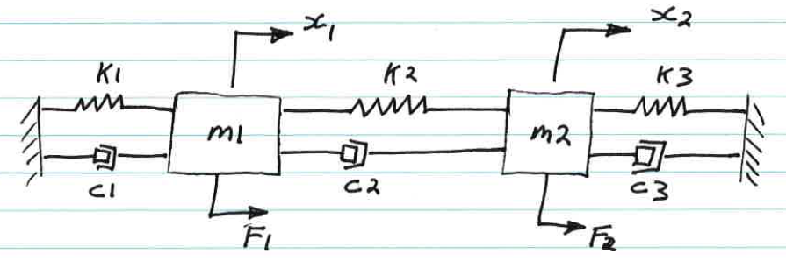 

In this tutorial we're going to look at the following subtopics:

$\qquad \bullet
$ apply Newton's laws to derive the system's dynamic equation of motion

$\qquad \bullet $ solve **NUMERICALLY** the solution for the excitation case involving STEP functions

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

**Apply Newton's law:**

The free body diagram for this system is shown below:

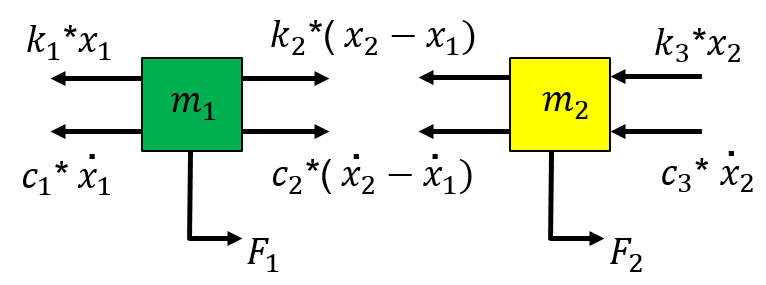

For the 1st mass we have:


$$m_1 \thinspace \ddot{x_1} = F_1 + k_2(x_2 - x_1) + c_2(\dot{x_2} - \dot{x_1}) - k_1x_1 - c_1 \dot{x_1}$$
 


$$m_1 \thinspace \ddot{x_1} = F_1  +  x_1(-k_2 + -k_1) +   x_2(k_2) +  \dot{x_1}(-c_2 + -c_1) +   \dot{x_2} (c_2) 
$$
 

For the 2nd mass we have:


$$m_2 \thinspace \ddot{x_2} = F_2 - k_2(x_2 - x_1) - c_2(\dot{x_2} - \dot{x_1}) - k_3x_2 - c_3 \dot{x_2}$$


 
$$m_2 \thinspace \ddot{x_2} = F_2  +  x_1(k_2) + x_2(-k_2 + -k_3) + \dot{x_1}(c_2) + \dot{x_2}(-c_2 + -c_3)$$


We can combine the two 2nd order ODEs into a matrix equation, ie:

$\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$. \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$ + $\pmatrix{
(c_1 + c_2) & -c_2 \cr
-c_2 & (c_2+c_3) \cr
}$$. \pmatrix{
\dot{x}_1 \cr
\dot{x}_2 \cr
}$ + $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & (k_2+k_3) \cr
}$$. \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{F}_1 \cr
{F}_2 \cr
}$

which we can refer to as:   

- $M \ddot{X} + C\dot{X} + KX = F$   where   $X \in R^{n\times1}$

**Define the Mechanical system parameters an system matrices:**

Note all parameters are in SI units, ie: *kg, N/m, N/(m/sec)*

params = bh_func_2dof_params()

params = struct with fields:
    m1: 10
    k1: 1000
    c1: 20
    m2: 1
    k2: 500
    c2: 50
    k3: 100
    c3: 10



m1 = params.m1 ;    m2 = params.m2 ; 
k1 = params.k1 ;    k2 = params.k2 ;    k3 = params.k3 ;
c1 = params.c1 ;    c2 = params.c2 ;    c3 = params.c3 ;


So the system matrices are:

Mm_mat  = [m1, 0;
            0,   m2  ]

Mm_mat =     10     0
     0     1



Km_mat  = [(k1+k2),   -k2;
              -k2,    (k2+k3) ]

Km_mat =         1500        -500
        -500         600



Cm_mat  = [(c1+c2), -c2;
           -c2,    (c2+c3) ];

**Define the INITIAL conditions of the system:**

Let's consider the system with the following initial conditions - all parameters are in SI units, ie: *(m) *and *(m/sec)*

- $\dot{x_1 } \left(0\right)=0$,     $x_1 \left(0\right)=\text{ }\text{ }1\text{ }$ 

- $\dot{x_2 } \left(0\right)=5$,     $x_2 \left(0\right)=-0\ldotp 5$  

init_x1dot =  0;     init_x1    =  1;
init_x2dot =  5;     init_x2    = -0.5;

## Define our system Excitation functions:

We'll create 2 function handles for our excitation forces:

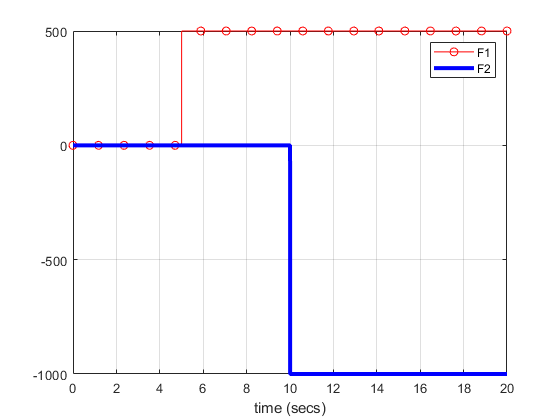

F1_fh  = @(t)    500*heaviside(t-5);
F2_fh  = @(t)  -1000*heaviside(t-10);

% visualise them
figure
    fplot(F1_fh, [-0.01, 20], '-ro');  hold on
    fplot(F2_fh, [-0.01, 20], '-b', 'LineWidth', 3);  
    
    legend({'F1','F2'}); 
    xlabel('time (secs)'); grid('on')

# Numerical solution:

At the heart of this approach are MATLAB's ODE solver suite - MATLAB has many ODE solver algorithms.  A good general purpose solver is the MATLAB function `ode45()` .  These numeric ODE solvers require you to package your problem into a 1st order form. 

- $\dot{y} =f\left(t,y\right)$     or     $M\left(t,y\right)\ldotp \dot{y} =f\left(t,y\right)$

For our Mechanical system the following form is a natural one to use:

                      $\pmatrix{
\ddot{X} \cr
\dot{X} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$\times \pmatrix{
\dot{X} \cr
X \cr
}$  +  $\pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$

which has the form:

                  
$$\dot{Z} = A \times Z + G$$
    

where:

-   $Z =  \pmatrix{
\dot{X} \cr
X \cr
} \in R^{2n \times 1}$   and    $G = \pmatrix{
M^{-1}{F} \cr
0_{n \times 1} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

So let's look at the example we solved previously:

% Define your INITIAL conditions
z_init = [init_x1dot;
          init_x2dot;
          init_x1;
          init_x2 ];

% define the system EXCITATION functions
Fsys_fh    = @(t) [  F1_fh(t); 
                     F2_fh(t) ];

% define the 1st order system to solve
%MY_SYSTEM = @(t, z) bh_mech_system(Mm_mat, Km_mat, Cm_mat, Fsys_fh, t, z);

% HEY: if you're using R2018a or NEWER, then try this one also
MY_SYSTEM = @(t, z)  bh_mech_system_LIVE(Mm_mat, Km_mat, Cm_mat, Fsys_fh, t, z);

% Define some ODE solver settings
t_span     = [0 20];
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

% use ODE45 to numerically solve your system
%[T,Y] = solver(odefun,   tspan,  z0,     options)
[T,Z]  = ode45(MY_SYSTEM, t_span, z_init, my_options);

## Plot the NUMERIC solution:

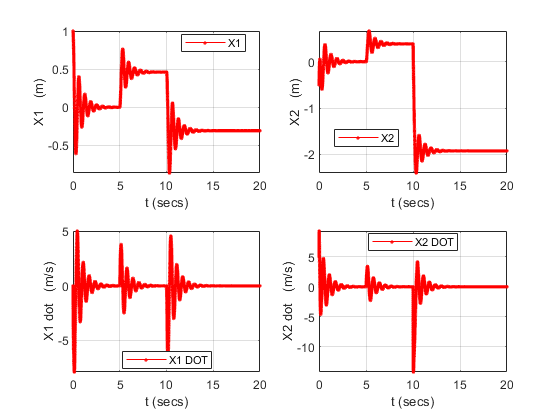

x1_dot  = Z(:,1); 
x2_dot  = Z(:,2);  
x1      = Z(:,3);  
x2      = Z(:,4);
t       = T;
LIN_SPEC = '-r.';

figure;
subplot(2,2,1);
   plot(t, x1, LIN_SPEC);      xlabel('t (secs)'); 
                               ylabel('X1   (m)'); grid('on'); 
                               axis('tight');
                               legend('X1', 'Location', 'best');
%----------------------------------------------------------------------- 
subplot(2,2,2);
   plot(t, x2, LIN_SPEC);  
                               xlabel('t (secs)'); 
                               ylabel('X2   (m)'); 
                               grid('on'); axis('tight');
                               legend('X2', 'Location', 'best');
%-----------------------------------------------------------------------                               
subplot(2,2,3);
   plot(t, x1_dot, LIN_SPEC);  
                               xlabel('t (secs)'); 
                               ylabel('X1 dot   (m/s)'); 
                               grid('on'); axis('tight');
                               legend('X1 DOT', 'Location', 'best');
%----------------------------------------------------------------------- 
subplot(2,2,4);
   plot(t, x2_dot, LIN_SPEC);  
                               xlabel('t (secs)'); 
                               ylabel('X2 dot   (m/s)'); 
                               grid('on'); axis('tight');
                               legend('X2 DOT', 'Location', 'best');

%-----------------------------------------------------------------------
   
